k2 =      1


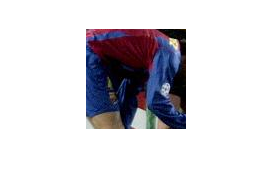

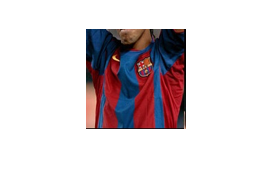

chiTotal =           8966.66666666667


k2 =      2


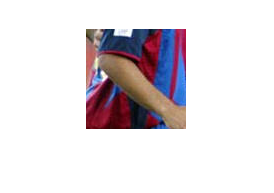

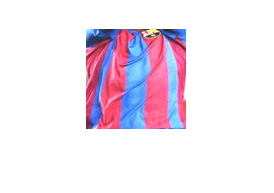

chiTotal =           8847.61904761905


k2 =      3


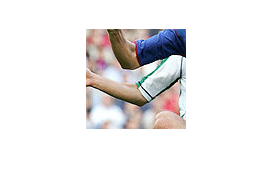

chiTotal =           8873.33333333333


k2 =      4


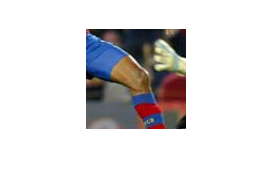

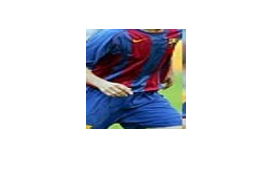

chiTotal =           8776.66666666667


k2 =      5


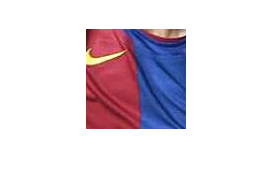

chiTotal =           8894.44444444445


k2 =      6


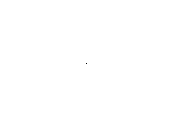

chiTotal =                 4294967296


k2 =      7


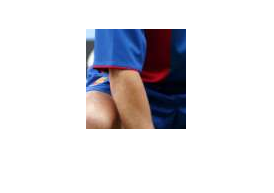

chiTotal =           8688.88888888889


k2 =      8


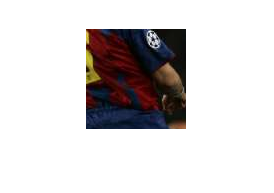

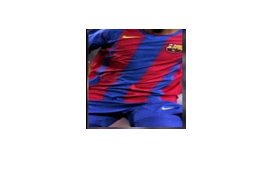

chiTotal =           8997.61904761905


k2 =      9


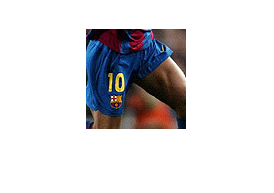

chiTotal =           8983.33333333333


k2 =     10


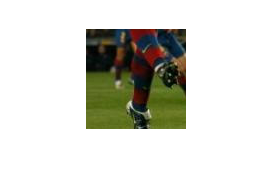

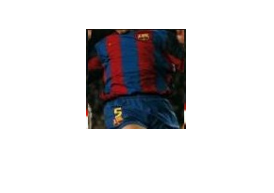

chiTotal =           8739.84126984127


k2 =     11


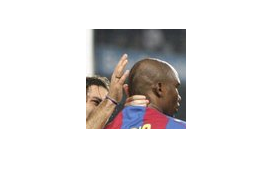

chiTotal =         8950


k2 =     12


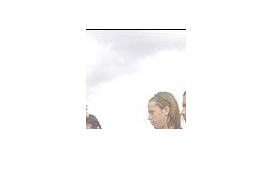

chiTotal =           8723.33333333333


k2 =     13


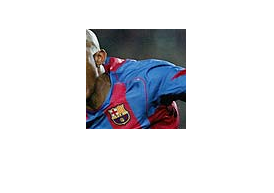

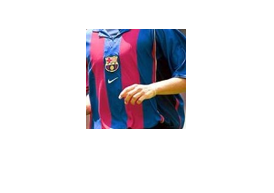

chiTotal =           8883.33333333333


k2 =     14


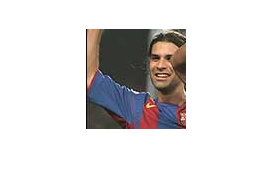

chiTotal =           8976.66666666667


k2 =     15


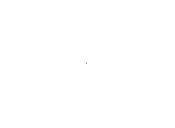

chiTotal =                 4294967296


k2 =     16


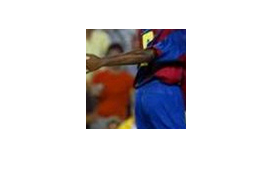

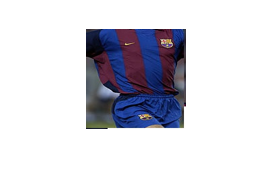

chiTotal =           8777.14285714286


k2 =     17


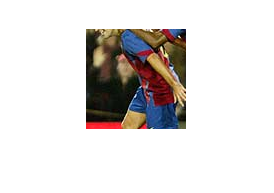

chiTotal =           8976.66666666667


k2 =     18


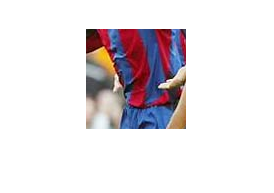

chiTotal =           8983.33333333333


k2 =     19


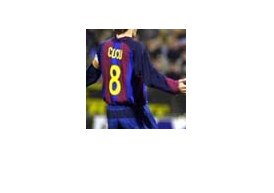

chiTotal =         8810


k2 =     20


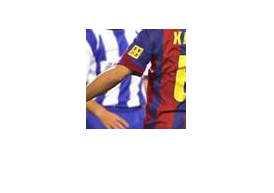

chiTotal =           8776.66666666667


k2 =     21


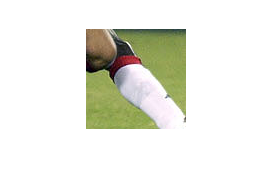

chiTotal =           8836.66666666667


k2 =     22


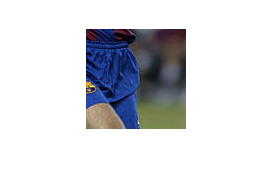

chiTotal =         8960


k2 =     23


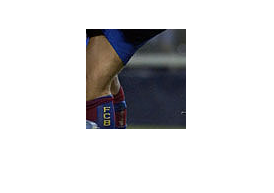

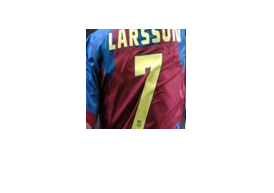

chiTotal =           8922.22222222222


k2 =     24


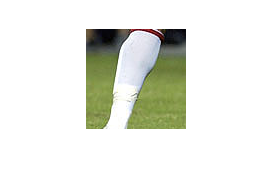

chiTotal =           8869.93006993007


k2 =     25


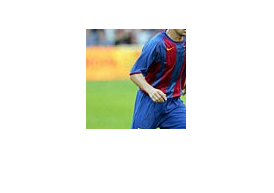

chiTotal =           8982.46753246753


k2 =     26


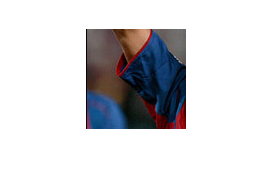

chiTotal =           8983.33333333333


k2 =     27


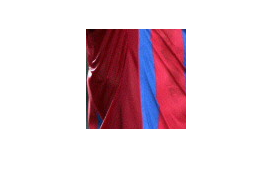

chiTotal =           8733.33333333333


k2 =     28


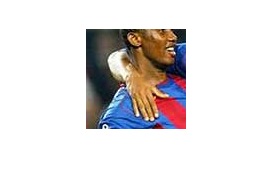

chiTotal =           8816.66666666667


k2 =     29


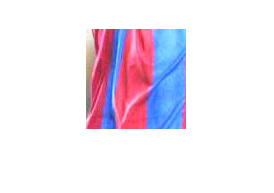

chiTotal =           8966.66666666667


k2 =     30


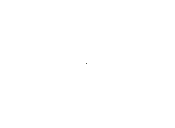

chiTotal =                 4294967296


k2 =     31


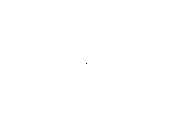

chiTotal =                 4294967296


k2 =     32


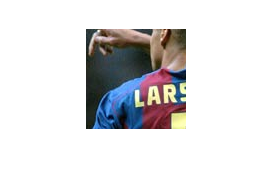

chiTotal =           8783.33333333333


k2 =     33


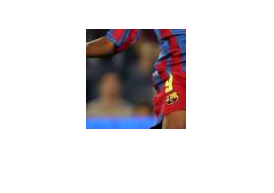

chiTotal =           8638.09523809524


k2 =     34


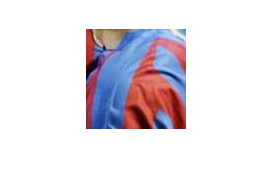

chiTotal =           8933.33333333333


k2 =     35


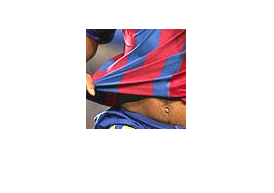

chiTotal =           8683.33333333333


k2 =     36


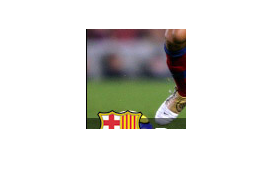

chiTotal =           8973.33333333333


k2 =     37


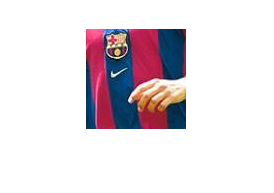

chiTotal =           8793.33333333333


k2 =     38


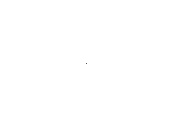

chiTotal =                 4294967296


k2 =     39


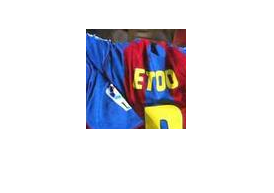

chiTotal =           8710.79365079365


k2 =     40


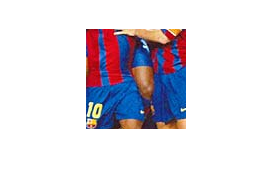

chiTotal =           8783.33333333333


ans =      0


clear
format long G
experimento("chi", "rgb", 100, 100, 1, 9000, 'barcelona')

function [pdd] = experimento(distance, space_color, size_windows, nbins, BD, error, team)
    pdd = 0;
    chiPrueba = 0;
    for k2 = 1:40
        k2
        if k2 < 10
                imTest = imread(strcat(team ,'\','0', int2str(k2) ,'.jpg'));
        else
                imTest = imread(strcat(team ,'\',int2str(k2) ,'.jpg'));
        end
        chiTotal = 2^32;
        [h, w, d] = size(imTest);
        height_of_the_windows = size_windows;
        width_of_the_windows = size_windows;
        pasos_y = 40;
        pasos_x = 40;
        i_total = 1;
        j_total = 1;
        i_total2 = 1;
        j_total2 = 1;
        for i = 1:pasos_y:(h-pasos_y-height_of_the_windows)
            salida = 0;
            for j = 1:pasos_x:(w-pasos_x-width_of_the_windows)
                height_of_the_windows_aux = height_of_the_windows;
                width_of_the_windows_aux = width_of_the_windows;
                if (i+height_of_the_windows> h)
                    height_of_the_windows_aux = h-i;
                end
                if (j+width_of_the_windows> w)
                    width_of_the_windows_aux = w-j;
                end
                subImagen = imTest(i:(i+height_of_the_windows_aux-1),j:(j+width_of_the_windows_aux-1),:);
                    for k = 1:10
                        im = imread(strcat('BD',int2str(BD),'\' ,int2str(k) ,'.jpg'));
                        im = imresize(im, [height_of_the_windows_aux width_of_the_windows_aux]);
                        if (space_color == "rgb")
                            [l1,rbsubImagen] = getHistoRGB(subImagen,nbins);
                            [l2,rbim] = getHistoRGB(im,nbins);
                        elseif(space_color == "hsv")
                            [l1,hs] = getHistoHSV(subImagen,nbins);
                            [l2,hs] = getHistoHSV(im,nbins);
                        end 
                        if (distance == "emd")
                            total = pdist2(rbsubImagen,rbim,'mahalanobis');
                            total = sum(sum(total));
                        elseif (distance == "euclidean")
                            total = distEuclidean(l1,l2);
                        elseif (distance == "kl")
                            total = distKL(l1,l2);
                        elseif (distance == "chi")
                            total = distChi(l1,l2);
                        end
                        
                        if (total < error)
                            %r = im;
                            %i_total = i;
                            %j_total = j;
                            %i_total2 = (i+height_of_the_windows_aux-1);
                            %j_total2 = (j+width_of_the_windows_aux-1);
                            %chiTotal = total;
                            salida = 1;
                            break;
                        end
                    end
                    if (salida == 1)
                        break;
                    end
            end
            if (salida ==1)
                %break;
            end
        end
        %figure
        %imshow(imTest(i_total:i_total2,j_total:j_total2,:))
        %figure 
        %imshow(r)
        %chiTotal
        %if (chiTotal > chiPrueba)
        %    chiPrueba = chiTotal;
        %end
    end
end

function d = distChi(l1,l2)
    aux = (l1 == l2);
    l1 = l1 + double(aux);
    l2 = l2 + double(aux);
    d = sum(sum(((l1-l2).^2)./(l1+l2)));
    d = d/2;
end
function d = distEuclidean(l1,l2)
    aux = (l1 == l2);
    l1 = l1 + double(aux);
    l2 = l2 + double(aux);
    d = sum(sum((l1-l2).^2));
end
function d = distKL(l1,l2)
    
end
function fval = distEMD(im1,im2,nbins);
    [f, fval] = test(im1,im1,nbins);
end
function  [h,hs] = getHistoHSV(im, NBINS)
    %hGaus = fspecial('gaussian', 10, 4);
    %im = imfilter(im,hGaus,'conv');
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    I = double(r)+double(g)+double(b);
    hsv = rgb2hsv(im);
    I = hsv(:,:,3)*max(max(max(I)));
    rn = uint8((double(r)./I)*255);
    gn = uint8((double(g)./I)*255);
    bn = uint8((double(b)./I)*255);
    rgbn = cat(3,rn,gn,bn);
    hsv = rgb2hsv(rgbn)
    h = hsv(:,:,1);
    s = hsv(:,:,2);
    [f c d] = size(im);
    x = [];
    y = [];
    for i = 1:f
        x2 = h(f,:);
        x = [x x2];
        y2 = s(f,:);
        y = [y y2];
    end
    x = x';
    y = y';
    hs = [x y]*256;
    h = hist3(hs,'nbins',[NBINS NBINS]);
end

function [h,rg] = getHistoRGB(im,NBINS)
    hGaus = fspecial('gaussian', 10, 4);
    im = imfilter(im,hGaus,'conv');
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    I = double(r)+double(g)+double(b);
    rn = double(uint8((double(r)./I)*255));
    bn = double(uint8((double(b)./I)*255));
    [f c d] = size(im);
    x = [];
    y = [];
    for i = 1:f
        x2 = rn(f,:);
        x = [x x2];
        y2 = bn(f,:);
        y = [y y2];
    end
    x = x';
    y = y';
    rg = [x y];
    h = hist3(rg,'nbins',[NBINS NBINS]);
end